# 4. Heat Transfer -

# thermalBC

[`thermalBC(thermalmodel,RegionType,RegionID,'Temperature',Tval)`](https://ww2.mathworks.cn/help/pde/ug/pde.thermalmodel.thermalbc.html#d120e93211)`:`将温度边界条件添加到`thermalmodel`。边界条件适用于`RegionType`ID编号为的类型区域`RegionID`。

[`thermalBC(thermalmodel,RegionType,RegionID,'HeatFlux',HFval)`](https://ww2.mathworks.cn/help/pde/ug/pde.thermalmodel.thermalbc.html#d120e93239)`:thermalBC`与`HeatFlux` 参数一起使用以指定流入或流出外部源的热通量。

[`thermalBC(thermalmodel,RegionType,RegionID,'ConvectionCoefficient',CCval,'AmbientTemperature',ATval)`](https://ww2.mathworks.cn/help/pde/ug/pde.thermalmodel.thermalbc.html#d120e93281)`:`将对流边界条件添加到`thermalmodel`。边界条件适用于`RegionType`ID编号为的类型区域`RegionID`。

[`thermalBC(thermalmodel,RegionType,RegionID,'Emissivity',REval,'AmbientTemperature',ATval)`](https://ww2.mathworks.cn/help/pde/ug/pde.thermalmodel.thermalbc.html#d120e93311)`:`将辐射边界条件添加到`thermalmodel`。边界条件适用于`RegionType`ID编号为的类型区域`RegionID`。

[`thermalBC = thermalBC(``___``)`](https://ww2.mathworks.cn/help/pde/ug/pde.thermalmodel.thermalbc.html#d120e93339)`:`返回热边界条件对象。

4.1**Specify Temperature on the Boundary**

% thermalmodel = createpde('thermal');
% aa=geometryFromEdges(thermalmodel,@squareg);%@squareg画一个单位正方形。
% thermalBC(thermalmodel,'Edge',[1,3],'Temperature',100)
% pdegplot(aa,'EdgeLabels','on')

4.2 **Specify Heat Coming Through the Boundary**

% thermalmodel = createpde('thermal','transient');
% gm = importGeometry(thermalmodel,'C:\Users\ZGY\Desktop\structure_heat_matlab\11.stl');
% pdegplot(gm,'FaceLabels','on')
% thermalBC(thermalmodel,'Face',[1,3],'HeatFlux',20)

4.3 **Specify Convection on the Boundary**

% thermalModel = createpde('thermal','transient');
% gm = importGeometry(thermalModel,'C:\Users\ZGY\Desktop\structure_heat_matlab\11.stl');
% pdegplot(gm,'FaceLabels','on')
% thermalBC(thermalModel,'Face',[2 4 5 6], ...
%                        'ConvectionCoefficient',5, ...
%                        'AmbientTemperature',27)

4.4 **Specify Radiation Through the Boundary**

Apply radiation boundary condition on four faces of a block.

% thermalmodel = createpde('thermal','transient');
% gm = importGeometry(thermalmodel,'C:\Users\ZGY\Desktop\structure_heat_matlab\11.stl');
% thermalmodel.StefanBoltzmannConstant = 5.670373E-8;
% thermalBC(thermalmodel,'Face',[2,4,5,6],...
%                        'Emissivity',0.1,...
%                        'AmbientTemperature',300)

4.5 **Specify Nonconstant Thermal Boundary Conditions**

Use function handles to specify thermal boundary conditions that depend on coordinates.

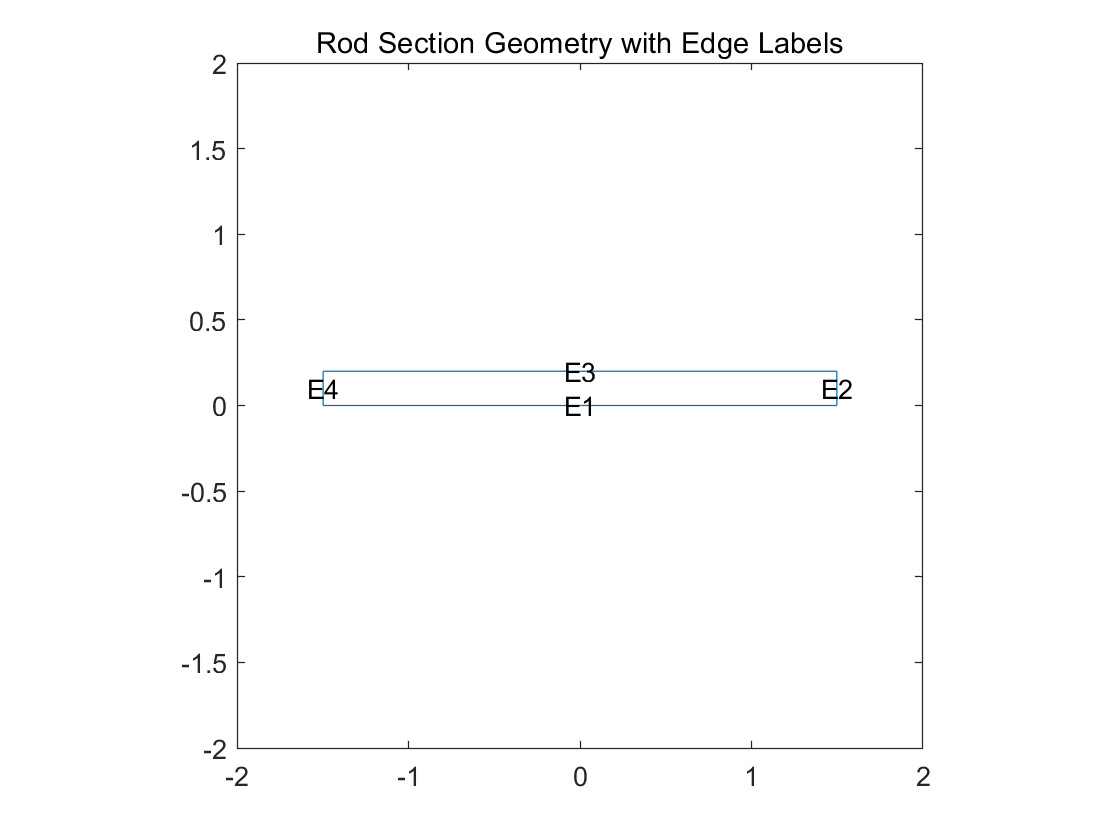

thermalmodel = createpde('thermal','transient');
g = decsg([3 4 -1.5 1.5 1.5 -1.5 0 0 .2 .2]');
geometryFromEdges(thermalmodel,g);
pdegplot(thermalmodel,'EdgeLabels','on');
xlim([-2 2]);
ylim([-2 2]);
title 'Rod Section Geometry with Edge Labels';

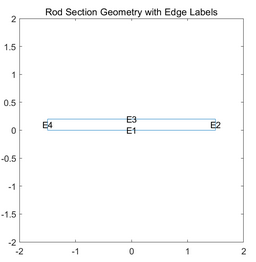

Assume that there is a heat source at the left end of the rod and a fixed temperature at the right end. The outer surface of the rod exchanges heat with the environment due to convection.

Define the boundary conditions for the model. The edge at *y *= 0 (edge 1) is along the axis of symmetry. No heat is transferred in the direction normal to this edge. This boundary is modeled as an insulated boundary, by default.(不标注的情况默认为绝热边界。)

The temperature at the right end of the rod (edge 2) is a fixed temperature, T = 100 C. Specify the boundary condition for edge 2 as follows.

thermalBC(thermalmodel,'Edge',2,'Temperature',100)

The convection coefficient for the outer surface of the rod (edge 3) depends on the *y*-coordinate, 50*y.* Specify the boundary condition for this edge as follows.

outerCC = @(location,~) 50*location.y;
thermalBC(thermalmodel,'Edge',3,...
                       'ConvectionCoefficient',outerCC,...
                       'AmbientTemperature',100)

The heat flux at the left end of the rod (edge 4) is also a function of the *y*-coordinate, 5000*y. *Specify the boundary condition for this edge as follows.

leftHF = @(location,~) 5000*location.y;
thermalBC(thermalmodel,'Edge',4,'HeatFlux',leftHF)